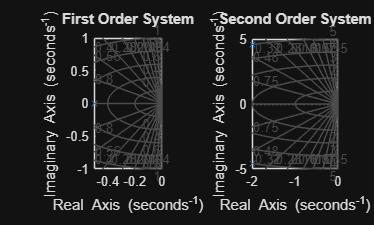

clc;
clear;
close all;

%% FIRST ORDER SYSTEM
K = 5;
tau = 2;

G1 = tf(K,[tau 1]);

figure;
subplot(1,2,1)
pzmap(G1)
grid on
title('First Order System')

%% SECOND ORDER SYSTEM
wn = 5;
zeta = 0.4;

G2 = tf([wn^2],[1 2*zeta*wn wn^2]);

subplot(1,2,2)
pzmap(G2)
grid on
title('Second Order System')


%% Display poles and zeros
disp('First Order System')

First Order System


pole(G1)

ans = -0.5000

zero(G1)


ans =

  0×1 empty double column vector




disp('Second Order System')

Second Order System


pole(G2)

ans =   -2.0000 + 4.5826i
  -2.0000 - 4.5826i


zero(G2)


ans =

  0×1 empty double column vector

